clear; clc; close all
load slope1.mat; 
%Convert X from latitude to meters
X=(X-X(end))*111139; %m 
X= fliplr(X)/(-1); 
Z1= fliplr(Z);
Z=Z1;



dx=X(2);
C=1;
u=.0005; %m/years
dt=C*dx/u;
m=length(X);


% Hillsope Diffusion
C_D=.1; 
D=.0003; %3 cm/100 yrs -> 3 m/yr;


n=1000;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 


M = sparse(m,m);
for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-2*C_D;
        elseif i-1==j
            M(i,j) = C_D;
        elseif i+1==j
            M(i,j) = C_D;
        end
    end
end
    

Z=Zik(:,1);
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end


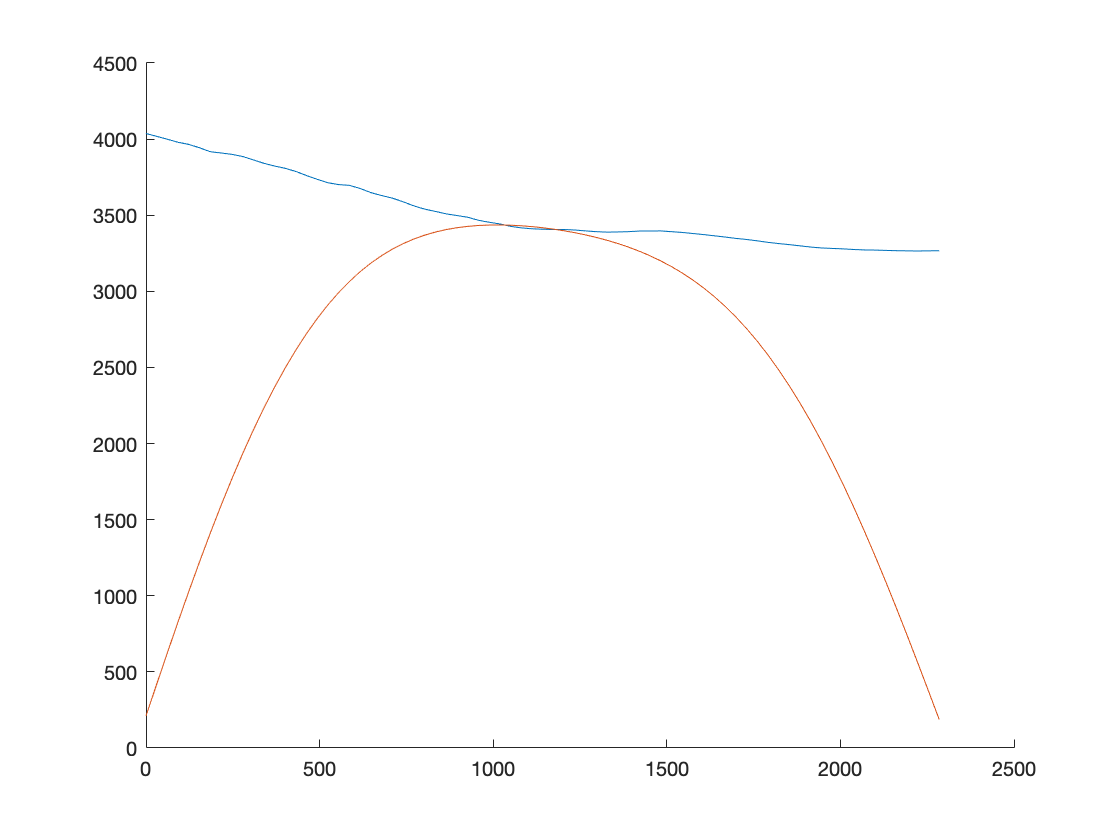

figure(1)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,1000))


% Basic Advection
dx=X(2);
C=1;
u=.0005; %m/years
dt=C*dx/u;
m=length(X);

n=1000; %timesteps
tf=n*dt;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 

M=sparse(m,m)

M =    All zero sparse: 75×75


for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-C;
        elseif i-1==j
            M(i,j) = C;
        end
    end
end
M(1,1)=1;

Z=Z1';
Zik(:,1)=Z;
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

figure(2)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,50))

% Advection-Diffusion
dx=X(2);
C=1;
u=.0005; %m/years
dt=C*dx/u;
m=length(X);

n=1000; %timesteps
tf=n*dt;

Zik=nan.*ones(length(Z),n);
Zik(:,1)=Z; 


M=sparse(m,m)

M =    All zero sparse: 75×75


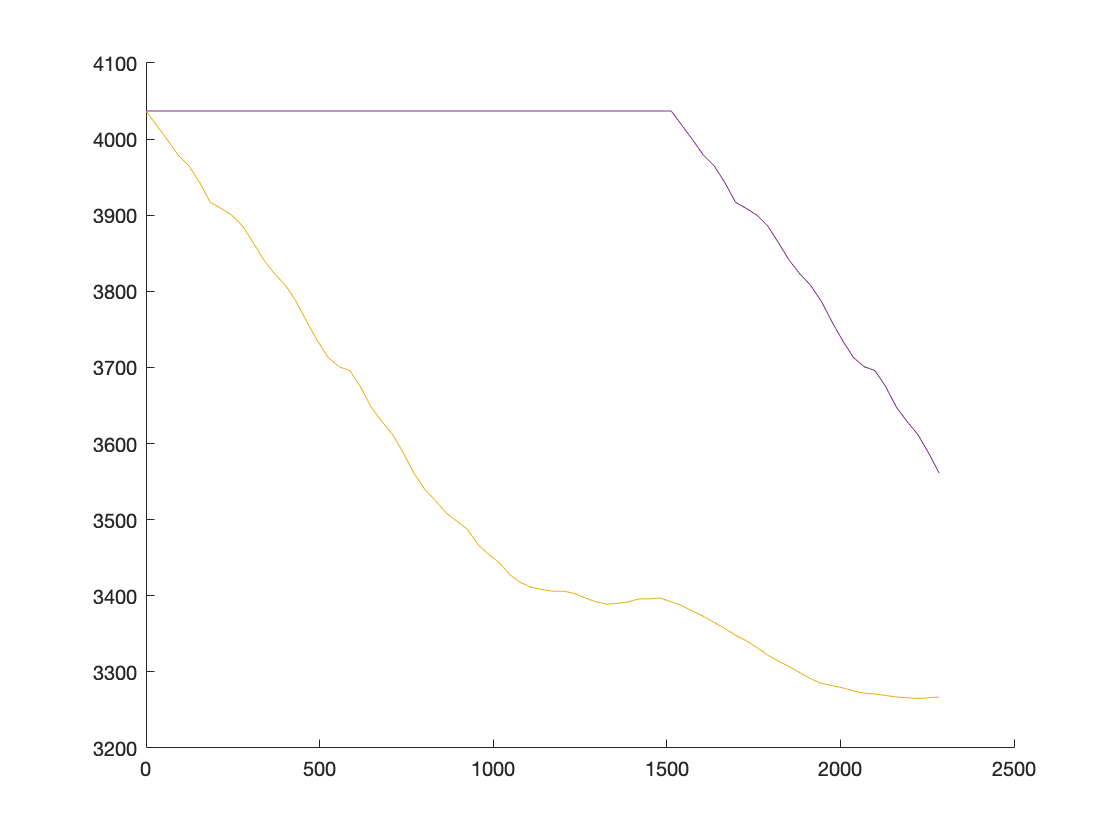

for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-C;
        elseif i-1==j
            M(i,j) = C;
        end
    end
end
M(1,1)=1;

Z=Z1';
Zik(:,1)=Z;
for i=1:(n); 
    Znew=M*Z;
    Zik(:,i+1)=Znew;
    Z=Znew;
end

Z_slope=nan.*ones(length(Z),n);
Z_slope(:,1)=1;
for i=(1:m-1);
    for j=2:m;
        points = nan.*ones(2,1);
        points(1) = Zik(i,j-1);
        points(2) = Zik(i+1,j-1);
        Z_slope(i,j)=(points(1)-points(2)) / norm(points);
    end
end

figure(2)
hold on
plot(X,Zik(:,1))
plot(X,Zik(:,50))